## 程序化拟合

• 两个 MATLAB 函数可以使用多项式来模拟您的数据。

• `polyfit(x,y,n)`通过最小化数据与模型的偏差平方和（最小二乘拟合），找到与 y 数据拟合的 n 次多项式 p(x) 的系数。

• `polyval(p,x)`返回由 `polyfit`确定的 n 次多项式在 x 处求值的结果。

### 多项式模型

在时间 t 的几个值上测量量 y。

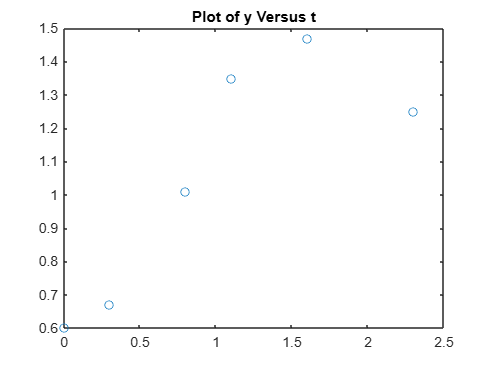

t = [0 0.3 0.8 1.1 1.6 2.3];
y = [0.6 0.67 1.01 1.35 1.47 1.25];
plot(t,y,'o')
title('Plot of y Versus t')

尝试使用二次多项式函数模拟此数据


$$y=a_2 t^2 +a_1 t+a_0$$


t = [0 0.3 0.8 1.1 1.6 2.3];
y = [0.6 0.67 1.01 1.35 1.47 1.25];
plot(t,y,'o')
title('Plot of y Versus t')

p = polyfit(t,y,2)

p =    -0.2942    1.0231    0.4981


数据的二次多项式模型由以下方程给出


$$y=-0\ldotp 2942t^2 +1\ldotp 0231t+0\ldotp 4981$$


在均匀间隔的时间点 t2 上计算多项式。然后，在同一图上绘制原始数据和模型。

t = [0 0.3 0.8 1.1 1.6 2.3];
y = [0.6 0.67 1.01 1.35 1.47 1.25];
plot(t,y,'o')
title('Plot of y Versus t')

p = polyfit(t,y,2)

p =    -0.2942    1.0231    0.4981


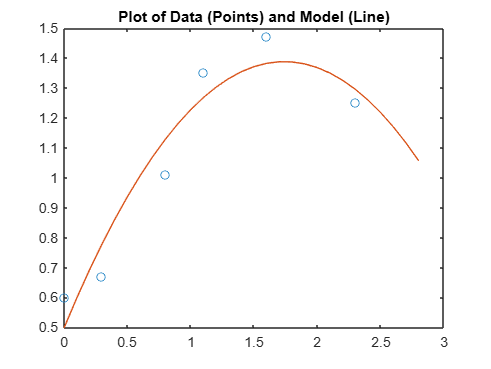

t2 = 0:0.1:2.8;
y2 = polyval(p,t2);
figure
plot(t,y,'o',t2,y2)
title('Plot of Data (Points) and Model (Line)')

**• **二次拟合大致遵循数据的基本形状，但未能捕捉到平滑的曲线。

**• **五次多项式能更好地跟随数据的波动。

t = [0 0.3 0.8 1.1 1.6 2.3];
y = [0.6 0.67 1.01 1.35 1.47 1.25];
plot(t,y,'o')
title('Plot of y Versus t')

p = polyfit(t,y,2)

p =    -0.2942    1.0231    0.4981


t2 = 0:0.1:2.8;
y2 = polyval(p,t2);
figure
plot(t,y,'o',t2,y2)
title('Plot of Data (Points) and Model (Line)')

p5 = polyfit(t,y,5)

p5 =     0.7303   -3.5892    5.4281   -2.5175    0.5910    0.6000


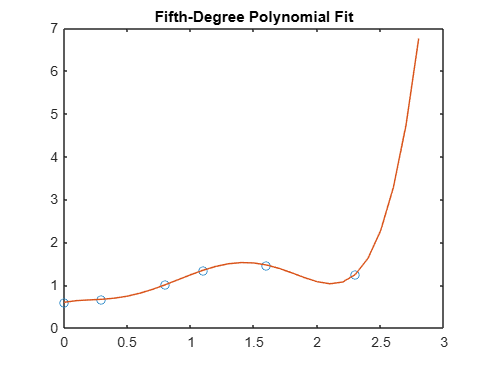

y3 = polyval(p5,t2);
figure
plot(t,y,'o',t2,y3)
title('Fifth-Degree Polynomial Fit')

### 带非多项式项的线性模型

• 当多项式函数不能产生令人满意的数据模型时的替代方案

• 考虑以下在参数$a_0$, $a_1$, $a_2$上是线性的，但在 t 数据上是非线性的函数：


$$y=a_0 +{a_1 e}^{-t} +a_2 te^{-t}$$


• 我们可以通过构建一个设计矩阵来实现这一点，其中每列代表一个用于预测响应的变量（模型中的一项），每行对应于这些变量的一次观测。

t = [0 0.3 0.8 1.1 1.6 2.3]';
y = [0.6 0.67 1.01 1.35 1.47 1.25]';
X = [ones(size(t)) exp(-t) t.*exp(-t)];
a = X\y

a =     1.3983
   -0.8860
    0.3085


现在在均匀间隔的点上评估模型，并将模型与原始数据一起绘制。

t = [0 0.3 0.8 1.1 1.6 2.3]';
y = [0.6 0.67 1.01 1.35 1.47 1.25]';
X = [ones(size(t)) exp(-t) t.*exp(-t)];
a = X\y

a =     1.3983
   -0.8860
    0.3085


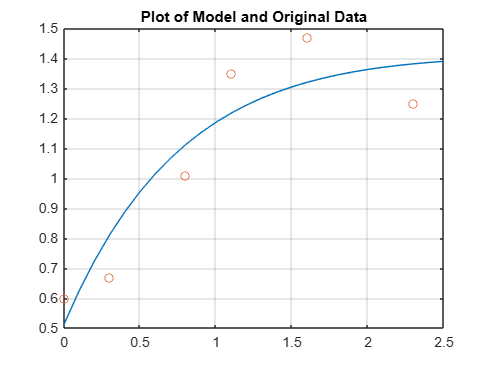

T = (0:0.1:2.5)';
Y = [ones(size(T)) exp(-T) T.*exp(-T)]*a;
plot(T,Y,'-',t,y,'o'), grid on
title('Plot of Model and Original Data')

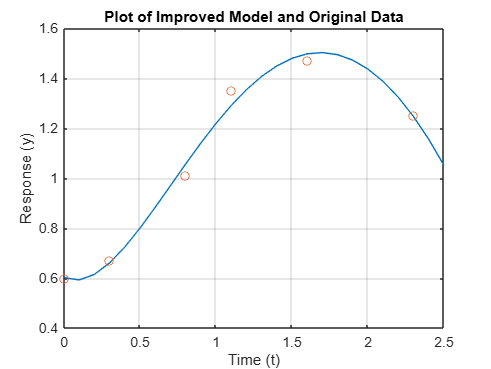

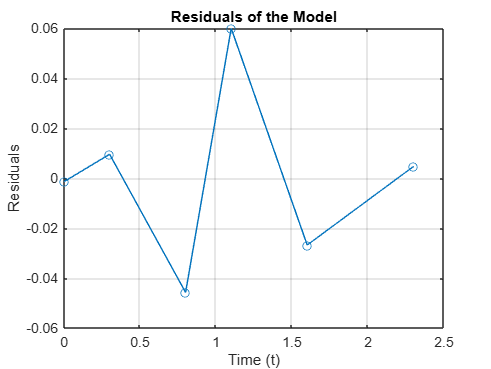

a =     0.1018
    0.4844
   -0.2847


MaxErr = 0.0038

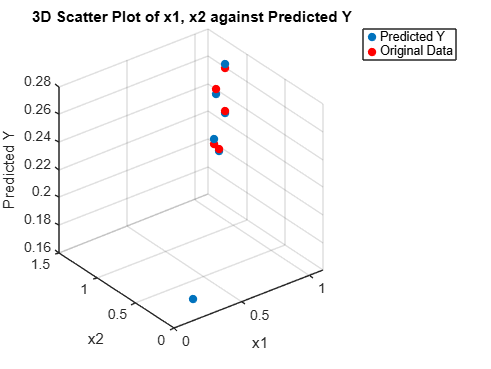

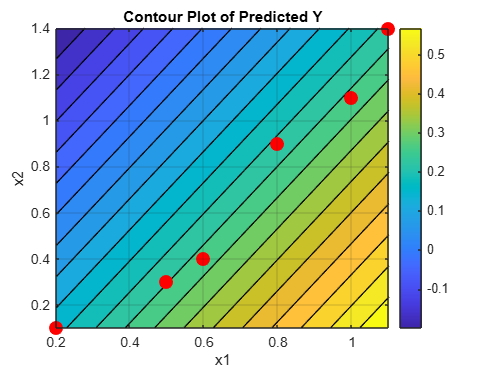

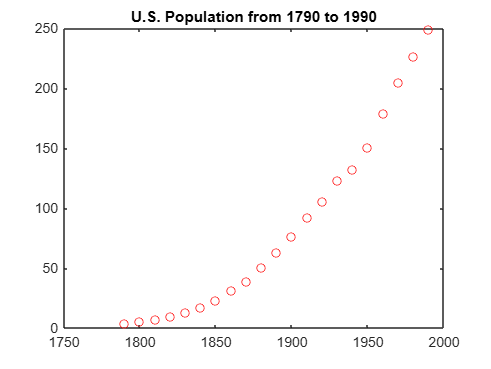

ans =     1.0000    0.9597
    0.9597    1.0000


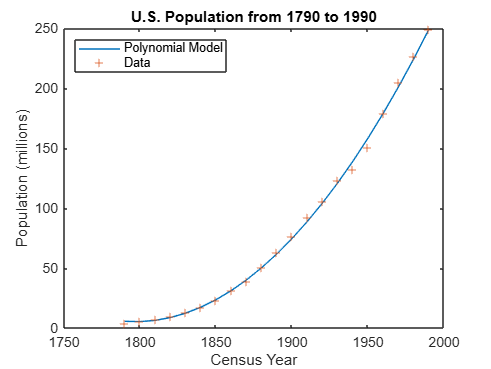

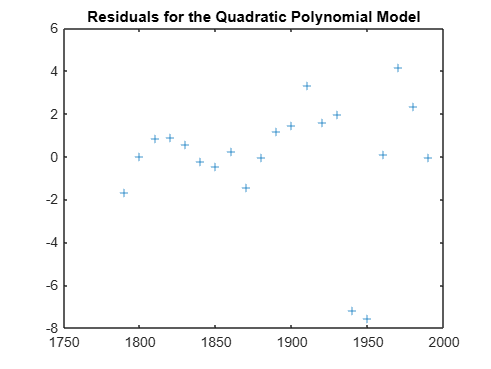

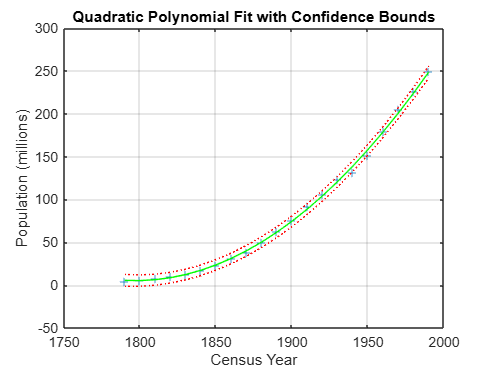

t = [0 0.3 0.8 1.1 1.6 2.3]';

y = [0.6 0.67 1.01 1.35 1.47 1.25]';

% 包含二次项
X = [ones(size(t)), exp(-t), t.*exp(-t), t.^2];

% 拟合模型
a = X\y;

% 生成预测
T = (0:0.1:2.5)';
Y = [ones(size(T)), exp(-T), T.*exp(-T), T.^2]*a;

figure;
plot(T, Y, '-', t, y, 'o'), grid on
title('Plot of Improved Model and Original Data')
xlabel('Time (t)')
ylabel('Response (y)')

residuals = y - X*a;
figure;
plot(t, residuals, 'o-')
title('Residuals of the Model')
xlabel('Time (t)')
ylabel('Residuals')
grid on

### 多元回归

多元回归：当 y 是多个预测变量的函数时，表达变量之间关系的矩阵方程必须扩展以适应额外的数据。

例如：


$$y=a_0 +a_1 x_1 +a_2 x_2$$


• 多元回归通过最小化数据与模型的偏差平方和（最小二乘拟合）来求解未知系数$a_0$, $a_1$, and $a_2$

• 通过构建设计矩阵 X 来构造并求解方程组

• 测量量 y 在  $x_1$ and$\;x_2$ 的多个值下的值。将这些值存储在向量 $x_1$,$\;x_2$, and y, 

• 通过构建设计矩阵 X 来构造并求解方程组

x1 = [.2 .5 .6 .8 1.0 1.1]';
x2 = [.1 .3 .4 .9 1.1 1.4]';
y = [.17 .26 .28 .23 .27 .24]';
X = [ones(size(x1)) x1 x2];
a = X\y
Y = X*a;
MaxErr = max(abs(Y - y))

**• 问题：如何绘制这个？**

% 给定数据
x1 = [.2 .5 .6 .8 1.0 1.1]';
x2 = [.1 .3 .4 .9 1.1 1.4]';
y = [.17 .26 .28 .23 .27 .24]';
X = [ones(size(x1)) x1 x2];

% 拟合模型
a = X\y;
Y = X*a;

% 创建3D散点图
figure;
scatter3(x1, x2, Y, 'filled');
hold on;
scatter3(x1, x2, y, 'r', 'filled'); % 原始数据点
grid on;
xlabel('x1');
ylabel('x2');
zlabel('Predicted Y');
title('3D Scatter Plot of x1, x2 against Predicted Y');
legend('Predicted Y', 'Original Data');
hold off;

% 为等高线图创建 x1 和 x2 值的网格
[x1_grid, x2_grid] = meshgrid(linspace(min(x1), max(x1), 100), linspace(min(x2), max(x2), 100));
X_grid = [ones(numel(x1_grid), 1), x1_grid(:), x2_grid(:)];
Y_grid = X_grid * a;

% 为等高线绘图重塑 Y_grid
Y_grid = reshape(Y_grid, size(x1_grid));

% 创建等高线图
figure;
contourf(x1_grid, x2_grid, Y_grid, 20); % 20个等高线级别
colorbar;
hold on;
scatter(x1, x2, 100, 'r', 'filled'); % 原始数据点
grid on;
xlabel('x1');
ylabel('x2');
title('Contour Plot of Predicted Y');
hold off;

### 示例

典型的数据拟合过程包括以下步骤：

- 计算相关系数

- 将多项式拟合到数据

- 绘制并计算置信边界

- 示例：1790年至1990年的美国人口数据

load census
plot(cdate,pop,'ro')
title('U.S. Population from 1790 to 1990')

**计算相关系数**

load census
plot(cdate,pop,'ro')
title('U.S. Population from 1790 to 1990')
corrcoef(cdate,pop) 

- 对角矩阵元素表示每个变量与自身的完美相关性，等于1。

- 非对角元素非常接近1，表明变量 cdate 和 pop 之间存在强统计相关性。

**示例1-将多项式拟合到数据**

load census
plot(cdate,pop,'ro')
title('U.S. Population from 1790 to 1990')
[p,ErrorEst] = polyfit(cdate,pop,2);
pop_fit = polyval(p,cdate,ErrorEst);
plot(cdate,pop_fit,'-',cdate,pop,'+');
title('U.S. Population from 1790 to 1990')
legend('Polynomial Model','Data','Location','NorthWest');
xlabel('Census Year');
ylabel('Population (millions)');

**示例2-计算此拟合的残差**

load census
plot(cdate,pop,'ro')
title('U.S. Population from 1790 to 1990')
[p,ErrorEst] = polyfit(cdate,pop,2);
pop_fit = polyval(p,cdate,ErrorEst);
plot(cdate,pop_fit,'-',cdate,pop,'+');
title('U.S. Population from 1790 to 1990')
legend('Polynomial Model','Data','Location','NorthWest');
xlabel('Census Year');
ylabel('Population (millions)');
res = pop - pop_fit;
figure, plot(cdate,res,'+')
title('Residuals for the Quadratic Polynomial Model')

**示例3**

- 置信边界是预测响应的置信区间。区间的宽度表示拟合的确定程度。

- 95%的区间表示您有95%的把握新的观测值将落在边界内。

load census
plot(cdate,pop,'ro')
title('U.S. Population from 1790 to 1990')
[p,ErrorEst] = polyfit(cdate,pop,2);
pop_fit = polyval(p,cdate,ErrorEst);
plot(cdate,pop_fit,'-',cdate,pop,'+');
title('U.S. Population from 1790 to 1990')
legend('Polynomial Model','Data','Location','NorthWest');
xlabel('Census Year');
ylabel('Population (millions)');
res = pop - pop_fit;
figure, plot(cdate,res,'+')
title('Residuals for the Quadratic Polynomial Model')
[pop_fit,delta] = polyval(p,cdate,ErrorEst);
plot(cdate,pop,'+',cdate,pop_fit,'g-',cdate,pop_fit+2*delta,'r:',cdate,pop_fit-2*delta,'r:');
xlabel('Census Year');
ylabel('Population (millions)');
title('Quadratic Polynomial Fit with Confidence Bounds')
grid on